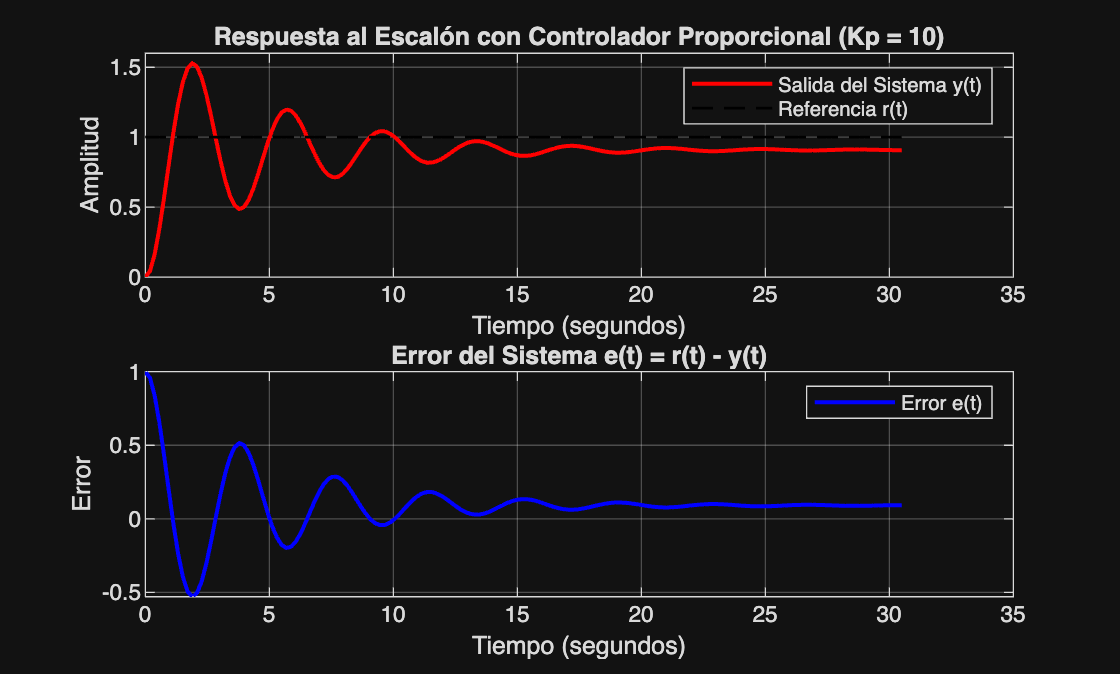

clear all
clc
num = [0.25];
den = [1, 0.4, 0.25];
G = tf(num, den);

Kp = 10; 
C = Kp;
% T(s) = (C*G) / (1 + C*G)
T = feedback(C * G, 1);

[y, t] = step(T); 

r = ones(size(y)); 

% 𝑒(𝑡)=𝑆𝑃−𝑃𝑉(𝑡)
error = r - y;

figure; 
subplot(2, 1, 1); 
plot(t, y, 'r-', 'LineWidth', 1.5);
hold on;
plot(t, r, 'k--', 'LineWidth', 1);
grid on;
title(['Respuesta al Escalón con Controlador Proporcional (Kp = ', num2str(Kp), ')']);
ylabel('Amplitud');
xlabel('Tiempo (segundos)');
legend('Salida del Sistema y(t)', 'Referencia r(t)');
ylim([0, 1.6]); 

subplot(2, 1, 2); 
plot(t, error, 'b-', 'LineWidth', 1.5);
grid on;
title('Error del Sistema e(t) = r(t) - y(t)');
ylabel('Error');
xlabel('Tiempo (segundos)');
legend('Error e(t)');
hold on


disp('Función de transferencia del sistema controlado T(s):')

Función de transferencia del sistema controlado T(s):


T


T =
 
         2.5
  ------------------
  s^2 + 0.4 s + 2.75
 
Continuous-time transfer function.


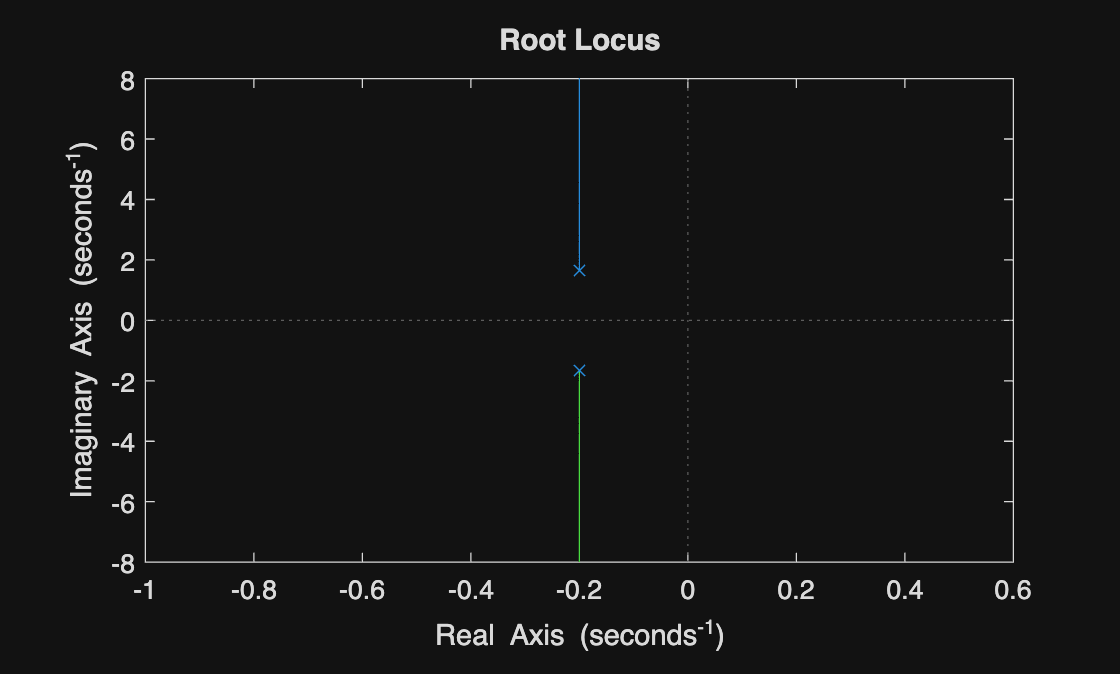

figure;
rlocus(T)